clear all
close all
clc

%--------------------------------------------------------------------------
% IMPOSTAZIONE CARTELLA
%--------------------------------------------------------------------------
cd(fileparts(matlab.desktop.editor.getActiveFilename));

%--------------------------------------------------------------------------
% LETTURA DEI DATI
%--------------------------------------------------------------------------

% Bode simulato (da Tina o simile)
tbl = readtable("dati/tcurve.txt", NumHeaderLines=3);
tbl.Properties.VariableNames = ["freq", "abs", "phase"];

% Dati sperimentali (ampiezza e fase con incertezze)
tbldata = readtable("dati/AD8031_Gain1e3.txt", NumHeaderLines=3);
tbldata.Properties.VariableNames = ["freq", "abs", "s_abs", "phase", "s_phase"];

% Dati FFT con alte frequenze
tblHf = readtable("FFT06.txt", NumHeaderLines=3);
tblHf.Properties.VariableNames = ["t", "Vin", "sVin", "Vout", "sVout"];

% Dati FFT con basse frequenze
tblLf = readtable("FFT07.txt", NumHeaderLines=3);
tblLf.Properties.VariableNames = ["t", "Vin", "sVin", "Vout", "sVout"];

%--------------------------------------------------------------------------
% ELABORAZIONE IMPULSO - ALTE FREQUENZE
%--------------------------------------------------------------------------

NHf = length(tblHf.Vout);
fsHf = 1 / min(diff(tblHf.t));

% FFT segnali
X_Hf = fft(tblHf.Vin);
Y_Hf = fft(tblHf.Vout);

% Funzione di trasferimento e incertezza
HvHf = Y_Hf ./ X_Hf;
sX_Hf = sqrt(sum(tblHf.sVin.^2)) * ones(size(X_Hf));
sY_Hf = sqrt(sum(tblHf.sVout.^2)) * ones(size(Y_Hf));
sHvHf = abs(HvHf) .* sqrt((sY_Hf ./ abs(Y_Hf)).^2 + (sX_Hf ./ abs(X_Hf)).^2);

% Tengo solo semispettro positivo
HvHf  = HvHf(1:NHf/2+1);
sHvHf = sHvHf(1:NHf/2+1);
fvHf  = (0:NHf/2) * fsHf / NHf;

% Filtro di frequenze utili
maskHf = fvHf < 1e5;
fvHf   = fvHf(maskHf);
HvHf   = HvHf(maskHf);
sHvHf  = sHvHf(maskHf);

%--------------------------------------------------------------------------
% ELABORAZIONE IMPULSO - BASSE FREQUENZE
%--------------------------------------------------------------------------

NLf = length(tblLf.Vout);
fsLf = 1 / min(diff(tblLf.t));

X_Lf = fft(tblLf.Vin);
Y_Lf = fft(tblLf.Vout);

HvLf = Y_Lf ./ X_Lf;
sX_Lf = sqrt(sum(tblLf.sVin.^2)) * ones(size(X_Lf));
sY_Lf = sqrt(sum(tblLf.sVout.^2)) * ones(size(Y_Lf));
sHvLf = abs(HvLf) .* sqrt((sY_Lf ./ abs(Y_Lf)).^2 + (sX_Lf ./ abs(X_Lf)).^2);

HvLf  = HvLf(1:NLf/2+1);
sHvLf = sHvLf(1:NLf/2+1);
fvLf  = (0:NLf/2) * fsLf / NLf;

maskLf = (fvLf > 1) & (fvLf < 1e4);
fvLf   = fvLf(maskLf);
HvLf   = HvLf(maskLf);
sHvLf  = sHvLf(maskLf);




%--------------------------------------------------------------------------
% FIT DEL MODELLO TEORICO
%--------------------------------------------------------------------------

% Conversione in modulo lineare
tbl.abs = 10.^(tbl.abs/20);

% Parametri iniziali del circuito
R1 = 99.9e3;
C1 = 100e-9;
R2 = 994;
C2 = 47e-9;

t1 = R1*C1;
t2 = R2*C2;

% Guess iniziale
p0 = [t1, t2, R1, C2];

% Funzioni di trasferimento
H = @(p,f) (1j*2*pi*f.*p(1)) ./ ...
           ((1 + 1j*2*pi*f.*p(1)) .* (1 + 1j*2*pi*f.*p(2)) + 1j*2*pi*f.*p(3).*p(4));


% Modulo e fase
G = @(p,f) abs(H(p,f));
A = @(p,f) angle(H(p,f));

% Pesi del fit
covabs   = 1 ./ tbldata.s_abs.^2;
covphase = 1 ./ tbldata.s_phase.^2;

% Fit non lineare (ampiezza e fase)
[popt,   R,   J,   ccovm,   MSE]   = nlinfit(tbldata.freq, tbldata.abs,   G, p0, "Weights", covabs);

[poptph, Rph, Jph, ccovmph, MSEph] = nlinfit(tbldata.freq, tbldata.phase, A, p0, "Weights", covphase);

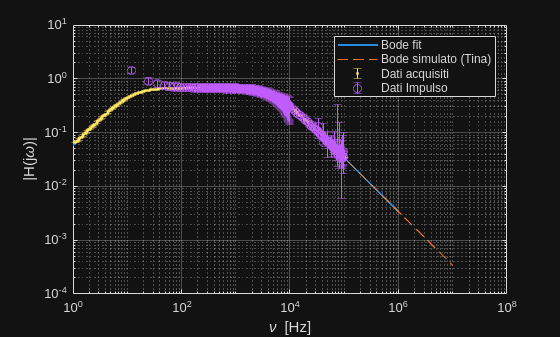



%--------------------------------------------------------------------------
% ELABORAZIONE IMPULSO : UNISCO I DUE CASI E FITTINO
%--------------------------------------------------------------------------

Hv=[HvLf',HvHf'];
sHv=[sHvLf',sHvHf'];
fv=[fvLf,fvHf];



%--------------------------------------------------------------------------
% RISULTATI DEL FIT
%--------------------------------------------------------------------------

x = logspace(0, 6, 10000);

y = H(popt, x);


%--------------------------------------------------------------------------
% GRAFICO: MODULO
%--------------------------------------------------------------------------
figure
loglog(x, abs(y), 'LineWidth', 1.5)
hold on
loglog(tbl.freq, tbl.abs, '--')
errorbar(tbldata.freq, tbldata.abs, tbldata.s_abs, '.')
errorbar(fv, abs(Hv), sHv, 'o')
hold off
legend("Bode fit", "Bode simulato (Tina)", "Dati acquisiti", "Dati Impulso ")
xlabel('\nu [Hz]')
ylabel('|H(j\omega)|')
grid on
saveas(gcf,"Misura_CRRC+pulse.pdf")

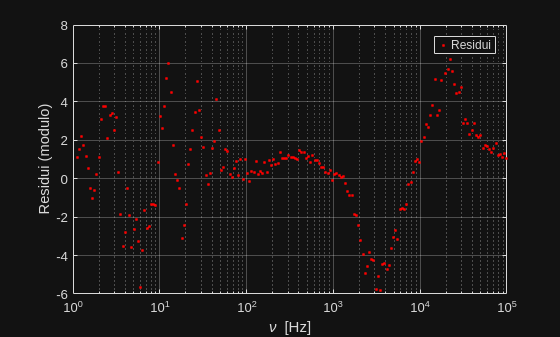



%--------------------------------------------------------------------------
% GRAFICO: RESIDUI
%--------------------------------------------------------------------------
figure
semilogx(tbldata.freq, R, '.r')
legend("Residui")
xlabel('\nu [Hz]')
ylabel('Residui (modulo)')
grid on

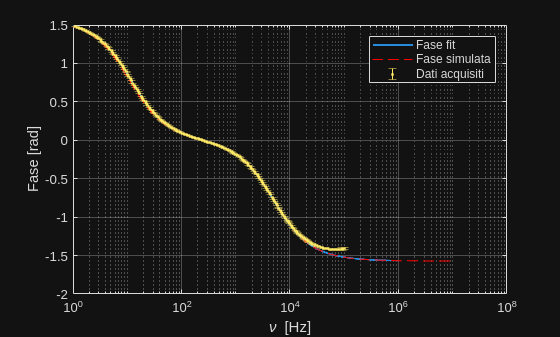


%--------------------------------------------------------------------------
% GRAFICO: FASE
%--------------------------------------------------------------------------
figure
semilogx(x, angle(y), 'LineWidth', 1.5)
hold on
plot(tbl.freq, tbl.phase*pi/180, 'r--')
errorbar(tbldata.freq, tbldata.phase, tbldata.s_phase, '.')
hold off
xlabel('\nu [Hz]')
ylabel('Fase [rad]')
legend("Fase fit", "Fase simulata", "Dati acquisiti")
grid on


%--------------------------------------------------------------------------
% STAMPA RISULTATI
%--------------------------------------------------------------------------
fprintf("=== RISULTATI FIT MODULO ===\n");

=== RISULTATI FIT MODULO ===


fprintf("popt = %.6e\n", popt);

popt = 9.149057e-03
popt = 4.678195e-05
popt = 9.619847e+04
popt = 4.510038e-08


fprintf("Incertezze = %.6e\n\n", sqrt(diag(ccovm)));

Incertezze = 1.161113e-06

Incertezze = 1.148539e-08

Incertezze = 4.625623e-24

Incertezze = 9.571855e-12




fprintf("=== RISULTATI FIT FASE ===\n");

=== RISULTATI FIT FASE ===


fprintf("poptph = %.6e\n", poptph);

poptph = 9.423202e-03
poptph = 4.508585e-05
poptph = 9.259764e+04
poptph = 4.374444e-08


fprintf("Incertezze = %.6e\n\n", sqrt(diag(ccovmph)));

Incertezze = 9.425687e-11

Incertezze = 1.966942e-08

Incertezze = 1.404008e-23

Incertezze = 3.060867e-11

